# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

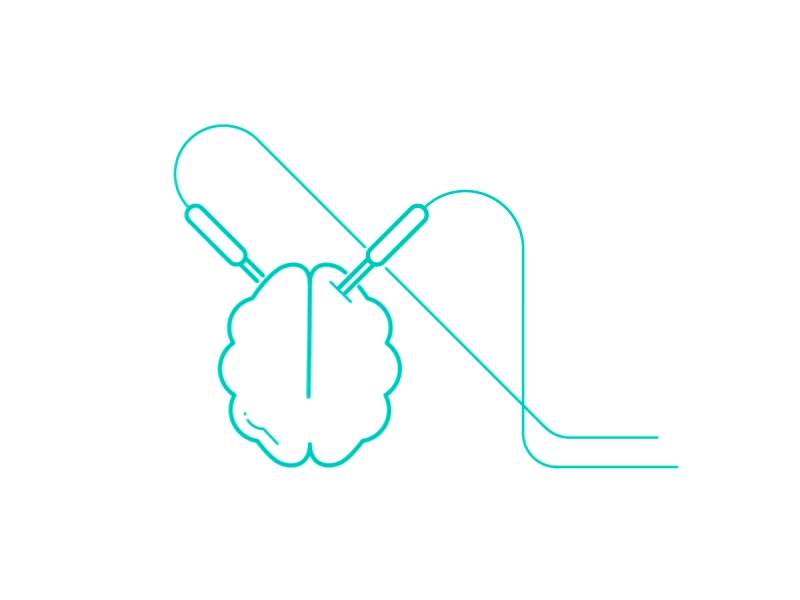

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

## 0. MainMenu

Deci = [];
Deci.Folder.Raw         = ['C:\Users\User\Desktop\NE329\Module3\RawData'];
Deci.SubjectList = 'gui';
Deci.Step               = 4;
Deci.Folder.Version     = ['C:\Users\User\Desktop\NE329\Module3\ProcessedData'];
Deci.Retroactive  = false;

## 1. Trial Definitions

Deci.DT.Type = 'TD_Module3';
Deci.DT.Starts     = {};                                                                      % Cell Array of Markers for Start codes.
Deci.DT.Ends       = {};                                                                      % Cell Array of Markers for End codes.
Deci.DT.Markers    = {[11 12] [101 100]};                                   % Cell Array of Markers for Trial Defs
Deci.DT.Locks      = [];                                                                % Num Array for each timelock (usually Stim, Rsp and Fdb Onset )
Deci.DT.Toi        = [-.5 1.5];   

## 2. PreProcessing Steps

Deci.PP = [];
%Deci.PP.filter.bpfreq = [1 30];
%Deci.PP.filter.bpfilter = 'yes';

Deci.PP.ShowData = false;
Deci.ICA.do = true;

## 3. Artifact Rejection

Deci.Art.do = true;
Deci.Art.crittoilim = [-.5 1.5];
Deci.Art.ShowArt = true;
Deci.Art.RT.locks = [2 1];
Deci.Art.RT.minlength = 200;
Deci.Art.RT.maxlength = 1200;

## 4. Analysis

Deci.Analysis.Laplace       =false;                                                               % Uses Captrak .bvct file with same name in RawData Folder
Deci.Analysis.DownSample    = 500;

Deci.Analysis.Locks         = [1 2];                                                          % Which Lock to Analyze
Deci.Analysis.LocksTitle    = {'Stim Onset' 'Rsp Onset'};                      % Folder Title to save each Lock as
Deci.Analysis.Conditions    = {[100] [101] [11] [12]};

Deci.Analysis.CondTitle     = {'Incorrect' 'Correct' 'Congruent' 'Incongruent'};

Deci.Analysis.Freq.do  = true;
Deci.Analysis.ERP.do  = true;

mycomputersucks = true;

Deci.Analysis.Freq.method        = 'wavelet';       
if mycomputersucks
Deci.Analysis.Freq.foi           = [6 12 24];                           % Frequency of Interest
Deci.Analysis.Freq.width         = [5 7.4 10];                                                         % Width
else
Deci.Analysis.Freq.foi           = exp(linspace(log(2),log(40),30));                           % Frequency of Interest
Deci.Analysis.Freq.width         = exp(linspace(log(3),log(13),30));                         
end
Deci.Analysis.Freq.gwidth        = 1;                                                          % Gwidth
Deci.Analysis.Toi           = [-.5 1.5];                                                  % Time Range to save
Deci.Analysis.Toilim        = [-2 3]; 

## 5. Plotting

Deci.Analysis.Version = [Deci.Folder.Version];
Deci.Plot.Figures      = [true true ];

Deci.Plot.BslRef = 'Rsp Onset';

Deci.Plot.Lock = Deci.Plot.BslRef;

if  strcmpi(Deci.Plot.BslRef,'Rsp Onset')
    
    Deci.Plot.Bsl     = [-.5 -.2];
    
    Deci.Plot.Math         = {'x1 -x2'};           % Condition Math done after Bsl, Condition Indexes are appended on.
    Deci.Plot.Draw         = {[1 2] [5]};                   % Cell array of Condition Index for each figure
    
    Deci.Plot.Title        = {'Incorrect vs Correct' 'Incorrect - Correct' };          % Title for each figure
    Deci.Plot.Subtitle     = {{'Incorrect' 'Correct'} {'Incorrect - Correct'}};     % Cell array of strings of subtitles for each Condition
    
    
else
    Deci.Plot.Bsl     = [-.2 0];

    
    Deci.Plot.Math         = {'x4 -x3'};           % Condition Math done after Bsl, Condition Indexes are appended on.
    Deci.Plot.Draw         = {[3 4] [5]};                   % Cell array of Condition Index for each figure
    
    Deci.Plot.Title        = {'Incongruent v Congruent' 'Incong - cong'};          % Title for each figure
    Deci.Plot.Subtitle     = {{'Congruent' 'Incongruent'} {'Incong - cong'}};     % Cell array of strings of subtitles for each Condition
    
end

Deci.Run.ERP =true;
Deci.Plot.GrandAverage = true;

Deci.Plot.Topo.do    =false;
Deci.Plot.Topo.Foi     = [4 7.5]; 
Deci.Plot.Topo.Toi     = [0 .2];                   % Time of Interest
Deci.Plot.Topo.Channel = ['Reinhart-All'];                   % Channel of Interest

Deci.Plot.Wire.do    =true;
Deci.Plot.Wire.Foi     = [4 7.5];
Deci.Plot.Wire.Channel =   {'FCz'};            % Channel of Interest
Deci.Plot.Wire.Toi     = [-.5 1];                   % Time of Interest

Deci.Plot.Bar.do    =false;
Deci.Plot.Bar.Foi     = [4 7.5];
Deci.Plot.Bar.Toi     = [0 .2];                    % Time of Interest
Deci.Plot.Bar.Channel =  {'FCz'};            % Channel of Interest

Deci.Plot.Stat.do = false; 

Deci_Backend(Deci);

Running Deci for 1 subjects
 
----------------------
Starting Analyzor for Subject #1: CC_EEG_s104_P
 
Downsampling Applied
 
---Starting Condition #1: Incorrect---
 
Applying Artifact Rejection
Final trial count is 30
!!!Trial Count for this condition is < 40, which is abnormally low!!!
 
---Starting Lock #1: Stim Onset---
 
the input is raw data with 64 channels and 30 trials


Error using dc_freqanalysis (line 50)
dc_freq is assumed to work only for trials with all equal length

Error in Analyzor (line 310)
                    Fourier = dc_freqanalysis(fcfg, tempdat);

Error in PC